%%%%%%%% Logic for comparing my RNA-seq with other RNA-seq

%%% A: Identify candidate genes (annotated, expressed across species)
    % 1: get the translation between Hg, Ms, Cy, entrez, ensembl, gene_symbol
    % 2: get the annotated orthologues among Hg, Cy, Ms (15220 genes)
    % 3: assign expressoion value to all the overlap genes and PCA them
    % 4: get the expressed orthologues (at least in one cell, log2(RPM+1) > 4
    % in at least one sample)

%%% B: Normalize expression (log2(X+1) -> zscore separately)
    % 1: read in all the datasets (my RNA-seq choose TPM, their choose RPM,
    % because they use SC3 RNA seq only identify mRNA 3' end, similar to TPM)
    % 2: log2(X+1) and then zscore them separately

%%% C: Visual analysis
    % 1: find corresponding normalized expression for all candiate genes
    % 2: PCA analysis (PC1 is referring to species, can check; PC2 is referring
    % to developmental stage? Draw with PC2 and PC3)
    % 3: other plots?


%%%%%%%% Additional information:
% v1_HgCyMs_translation (version 1) ---- all the genes align through
% species (18491 genes)
% v2_HgCyMs_translation (version 2) ---- genes have orthologs in three
% species (15150 genes, some genes couldn't find ensembl id through DAVID)
% v3_HgCyMs_translation (version 3) ---- v2 plus corresponding genes
% expression (order is Hg8, Cy421, Ms108)
% v4_HgCyMs_translation (version 4) ---- fill v3 empty cell with value 0
% v5_HgCyMs_translation (version 5) ---- zscore(expression level)
% separately in species and then combine them together


addpath(genpath('/Users/dududu/CRAZY_SCIENNY/RNA-Seq'));
addpath(genpath('/Users/dududu/CRAZY_SCIENNY/MATLAB'));

%%%%%%%% The part need to run everytime

%%% read in all the data source
    
% Read Cy and Ms RNA-seq files and transfer them into matrix
% (Cy is monkey and Ms is mice).
% From paper "A developmental coordinate of pluripotency among mice,
% monkeys and humans"
very_raw_Cy = readtable('ReadInFiles/From Nakamura 2016/GSE74767_SC3seq_Cy_ProcessedData.txt');
raw_Cy = table2cell(very_raw_Cy(:,:)); Cy_SampleNames = very_raw_Cy.Properties.VariableNames;
very_raw_Ms = readtable('ReadInFiles/From Nakamura 2016/GSE74767_SC3seq_Ms_ProcessedData.txt');
raw_Ms = table2cell(very_raw_Ms(:,:)); Ms_SampleNames = very_raw_Ms.Properties.VariableNames;

% Read my Hg RNA-seq files
%%% add column name in 'My Hg RNA-seq data.xls'
very_raw_Hg = readtable('ReadInFiles/MyCells/My Hg RNA-seq data TPM.xls');

raw_Hg = table2cell(very_raw_Hg(:,:)); Hg_SampleNames = very_raw_Hg.Properties.VariableNames;

load v5-Hg-Ms-Cy-translation.mat v5_HgCyMs_translation
load v4-Hg-Ms-Cy-translation.mat v4_HgCyMs_translation
load Cy_CellNames.mat Cy_CellNames; load Ms_CellNames.mat Ms_CellNames; load Hg_CellNames.mat Hg_CellNames;

## Color schematics

%%%%%%%% Cy more (more cell types)
CyColorPlus = [0.34,0.73,0.80;0.91,0.00,0.00;0.95,0.44,0.40;0.67,0.28,0.58;0.00,0.67,0.88;0.18,0.18,0.20;0.63,0.11,0.09;0.00,0.50,0.31;0.50,0.77,0.49;0.30,0.69,0.00;0.80,0.79,0.78;0.97,0.58,0.00;0.22,0.36,0.65];
%%%%%%%% Cy less (less cell types)
CyColor = [0.78,0.20,0.18;0.83,0.44,0.42;0.54,0.31,0.49;0.37,0.38,0.37;0.24,0.47,0.33;0.51,0.70,0.50;0.48,0.58,0.41];
%%%%%%%% Ms
MsColor = [0.76,0.87,0.44;0.00,0.71,0.93;0.30,0.73,0.00;0.20,0.39,0.70;1.00,0.38,0.00;0.00,0.53,0.31;0.46,0.25,0.61];

## version 2

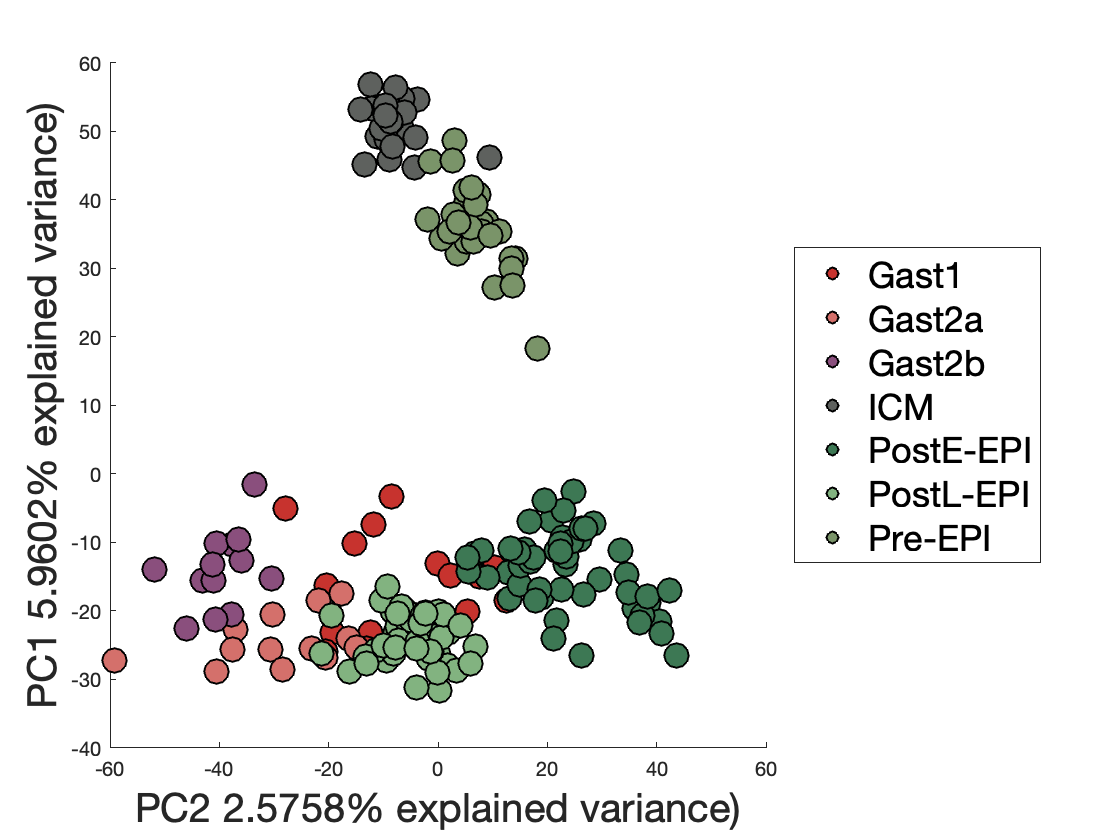

%%%%%% 1. Check if MATLAB pre-treat data
%%%%%% 2. If zscore affect PCA


%%%%%% 3. PCA Cy, Ms separately and then project my data onto it

    %%% PCA Cy alone (less cell one)
        % make matrix for pca
        celltypeIdx = [2:4,6,8:10];
        MatcolIdx = [];
        for ii = 1:length(celltypeIdx)
            MatcolIdx = [MatcolIdx, Cy_CellNames{celltypeIdx(ii),2}-2+15];
        end
        MatforPCA_Cy = cell2mat(v5_HgCyMs_translation(:,MatcolIdx));
        [coeff,score,latent,~,explained,~] = pca(MatforPCA_Cy');
        % plot data
        figure;
    %     subplot(1,2,1);
        PCxx = 2; PCyy = 1;
        for colIdx = 1:length(celltypeIdx)
            tempOGIdx = Cy_CellNames{celltypeIdx(colIdx),2}-2+15;
            tempEDIdx = [];
            for ii = 1:length(tempOGIdx)
                tempEDIdx = [tempEDIdx, find(MatcolIdx == tempOGIdx(ii))];
            end
            scatter(score(tempEDIdx,PCxx),score(tempEDIdx,PCyy),150,'MarkerEdgeColor',[0 0 0],'MarkerFaceColor',CyColor(colIdx,:),'LineWidth',1); hold on;
        end
        xeigenvalue = explained(PCxx);
        xlabel(['PC', num2str(PCxx), ' ', num2str(xeigenvalue),'% explained variance)'],'fontsize',20)
        % yeigenvalue = latent(2)/sum(latent);
        yeigenvalue = explained(PCyy);
    %     xlim([-150,150]); ylim([-150,150]);
        ylabel(['PC', num2str(PCyy), ' ', num2str(yeigenvalue),'% explained variance)'],'fontsize',20)
        legend('Gast1','Gast2a','Gast2b','ICM','PostE-EPI','PostL-EPI','Pre-EPI','Fontsize',18,'Location','eastoutside')
        hold off;

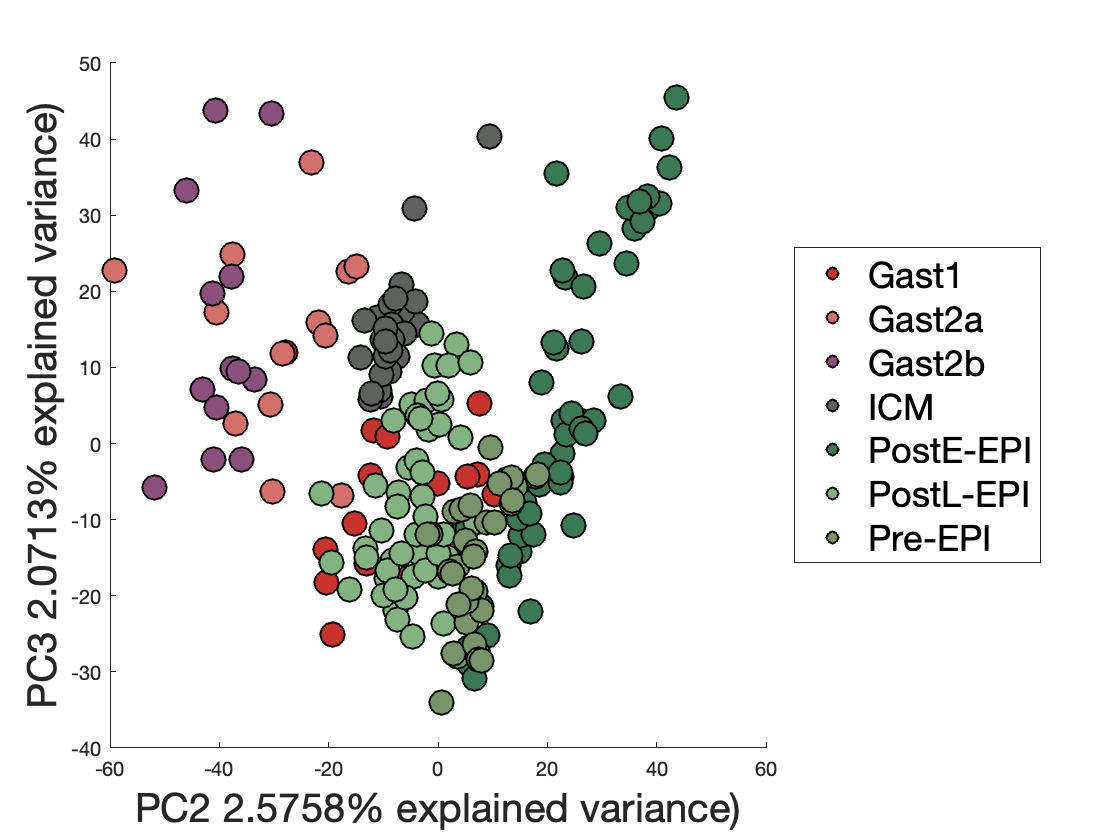

        figure;
    %     subplot(1,2,1);
        PCxx = 2; PCyy = 3;
        for colIdx = 1:length(celltypeIdx)
            tempOGIdx = Cy_CellNames{celltypeIdx(colIdx),2}-2+15;
            tempEDIdx = [];
            for ii = 1:length(tempOGIdx)
                tempEDIdx = [tempEDIdx, find(MatcolIdx == tempOGIdx(ii))];
            end
            scatter(score(tempEDIdx,PCxx),score(tempEDIdx,PCyy),150,'MarkerEdgeColor',[0 0 0],'MarkerFaceColor',CyColor(colIdx,:),'LineWidth',1); hold on;
        end
        xeigenvalue = explained(PCxx);
        xlabel(['PC', num2str(PCxx), ' ', num2str(xeigenvalue),'% explained variance)'],'fontsize',20)
        % yeigenvalue = latent(2)/sum(latent);
        yeigenvalue = explained(PCyy);
    %     xlim([-150,150]); ylim([-150,150]);
        ylabel(['PC', num2str(PCyy), ' ', num2str(yeigenvalue),'% explained variance)'],'fontsize',20)
        legend('Gast1','Gast2a','Gast2b','ICM','PostE-EPI','PostL-EPI','Pre-EPI','Fontsize',18,'Location','eastoutside')
        hold off;

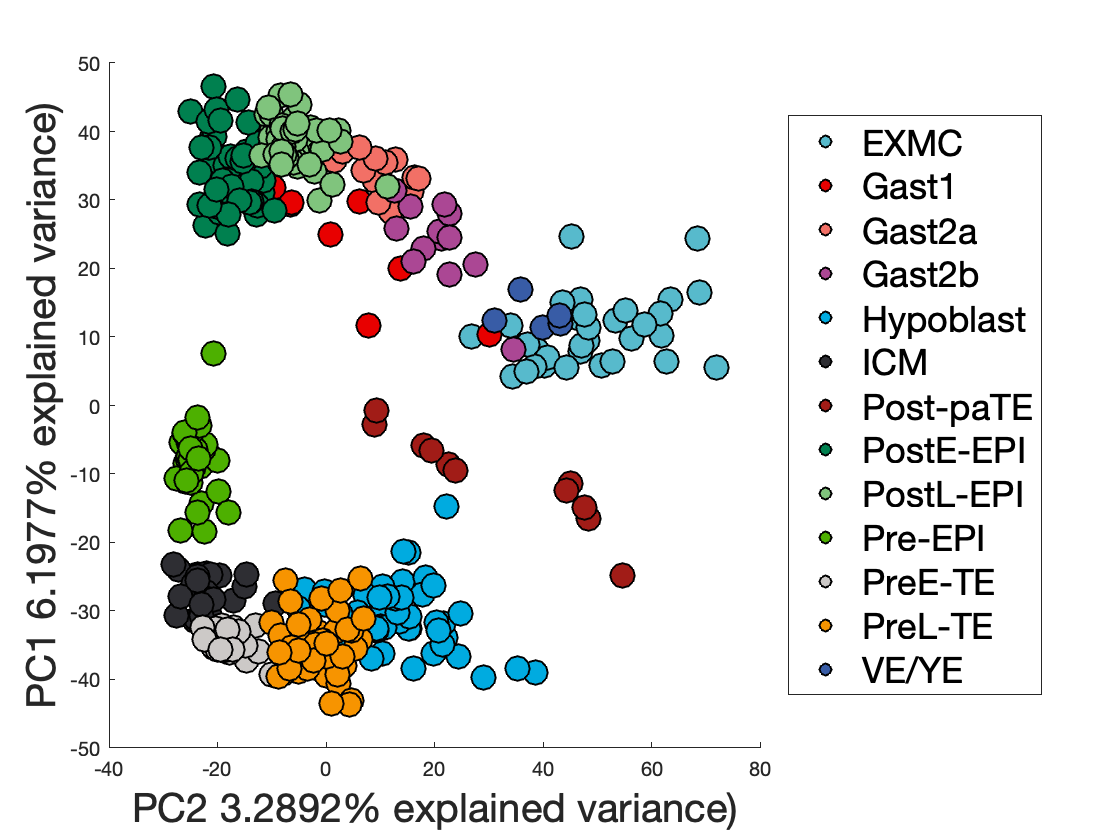

    %%% PCA Cy alone (more cell one)
        % make matrix for pca
        celltypeIdx = 1:13;
        MatcolIdx = [];
        for ii = 1:length(celltypeIdx)
            MatcolIdx = [MatcolIdx, Cy_CellNames{celltypeIdx(ii),2}-2+15];
        end
        MatforPCA_Cy = cell2mat(v5_HgCyMs_translation(:,MatcolIdx));
        [coeff,score,latent,~,explained,~] = pca(MatforPCA_Cy');
        % plot data
        figure;
    %     subplot(1,2,1);
        PCxx = 2; PCyy = 1;
        for colIdx = 1:length(celltypeIdx)
            tempOGIdx = Cy_CellNames{celltypeIdx(colIdx),2}-2+15;
            tempEDIdx = [];
            for ii = 1:length(tempOGIdx)
                tempEDIdx = [tempEDIdx, find(MatcolIdx == tempOGIdx(ii))];
            end
            scatter(score(tempEDIdx,PCxx),score(tempEDIdx,PCyy),150,'MarkerEdgeColor',[0 0 0],'MarkerFaceColor',CyColorPlus(colIdx,:),'LineWidth',1); hold on;
        end
        xeigenvalue = explained(PCxx);
        xlabel(['PC', num2str(PCxx), ' ', num2str(xeigenvalue),'% explained variance)'],'fontsize',20)
        % yeigenvalue = latent(2)/sum(latent);
        yeigenvalue = explained(PCyy);
    %     xlim([-150,150]); ylim([-150,150]);
        ylabel(['PC', num2str(PCyy), ' ', num2str(yeigenvalue),'% explained variance)'],'fontsize',20)
        legend('EXMC','Gast1','Gast2a','Gast2b','Hypoblast','ICM','Post-paTE','PostE-EPI','PostL-EPI','Pre-EPI','PreE-TE','PreL-TE','VE/YE','Fontsize',18,'Location','eastoutside')
        hold off;

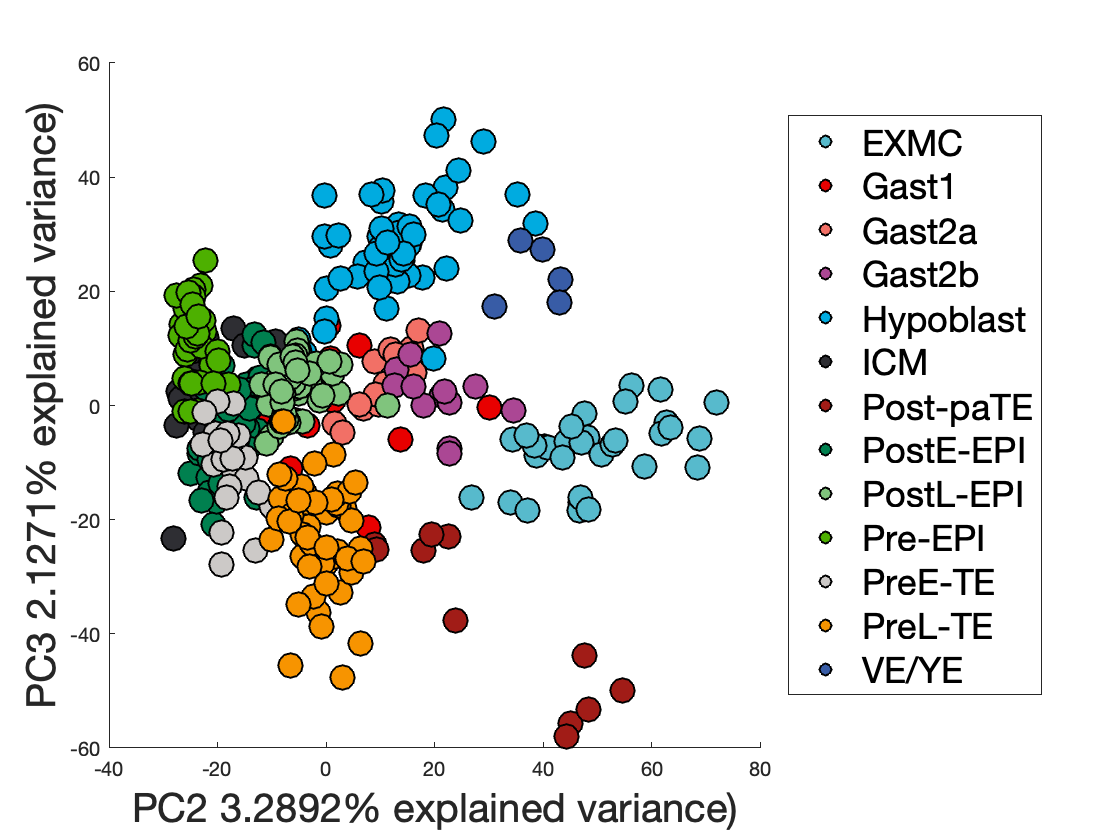

        figure;
    %     subplot(1,2,2);
        PCxx = 2; PCyy = 3;
        for colIdx = 1:length(celltypeIdx)
            tempOGIdx = Cy_CellNames{celltypeIdx(colIdx),2}-2+15;
            tempEDIdx = [];
            for ii = 1:length(tempOGIdx)
                tempEDIdx = [tempEDIdx, find(MatcolIdx == tempOGIdx(ii))];
            end
            scatter(score(tempEDIdx,PCxx),score(tempEDIdx,PCyy),150,'MarkerEdgeColor',[0 0 0],'MarkerFaceColor',CyColorPlus(colIdx,:),'LineWidth',1); hold on;
        end
        xeigenvalue = explained(PCxx);
        xlabel(['PC', num2str(PCxx), ' ', num2str(xeigenvalue),'% explained variance)'],'fontsize',20)
        % yeigenvalue = latent(2)/sum(latent);
        yeigenvalue = explained(PCyy);
    %     xlim([-150,150]); ylim([-150,150]);
        ylabel(['PC', num2str(PCyy), ' ', num2str(yeigenvalue),'% explained variance)'],'fontsize',20)
        legend('EXMC','Gast1','Gast2a','Gast2b','Hypoblast','ICM','Post-paTE','PostE-EPI','PostL-EPI','Pre-EPI','PreE-TE','PreL-TE','VE/YE','Fontsize',18,'Location','eastoutside')
        hold off;

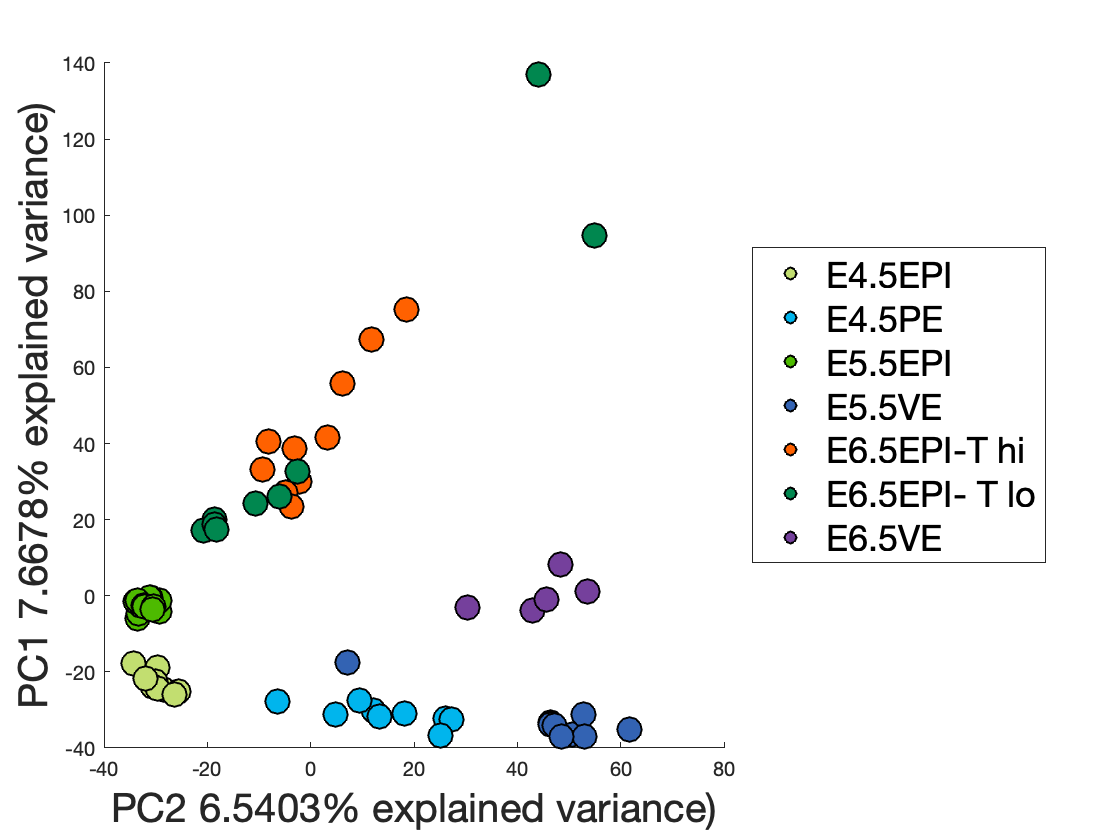

    %%% PCA Ms alone
        % make matrix for pca   
        celltypeIdx = [2:3,6:10];
        MatcolIdx = [];
        for ii = 1:length(celltypeIdx)
            MatcolIdx = [MatcolIdx, Ms_CellNames{celltypeIdx(ii),2}-2+436];
        end
        MatforPCA_Ms = cell2mat(v5_HgCyMs_translation(:,MatcolIdx));
        [coeff,score,latent,~,explained,~] = pca(MatforPCA_Ms');
        % plot data
        figure;
    %     subplot(1,2,1);
        PCxx = 2; PCyy = 1;
        for colIdx = 1:1:length(celltypeIdx)
            tempOGIdx = Ms_CellNames{celltypeIdx(colIdx),2}-2+436;
            tempEDIdx = [];
            for ii = 1:length(tempOGIdx)
                tempEDIdx = [tempEDIdx, find(MatcolIdx == tempOGIdx(ii))];
            end
            scatter(score(tempEDIdx,PCxx),score(tempEDIdx,PCyy),150,'MarkerEdgeColor',[0 0 0],'MarkerFaceColor',MsColor(colIdx,:),'LineWidth',1); hold on;
        end
        xeigenvalue = explained(PCxx);
        xlabel(['PC', num2str(PCxx), ' ', num2str(xeigenvalue),'% explained variance)'],'fontsize',20)
        % yeigenvalue = latent(2)/sum(latent);
        yeigenvalue = explained(PCyy);
        ylabel(['PC', num2str(PCyy), ' ', num2str(yeigenvalue),'% explained variance)'],'fontsize',20)
        legend('E4.5EPI','E4.5PE','E5.5EPI','E5.5VE','E6.5EPI-T hi','E6.5EPI- T lo','E6.5VE','Fontsize',18,'Location','eastoutside')
        hold off;

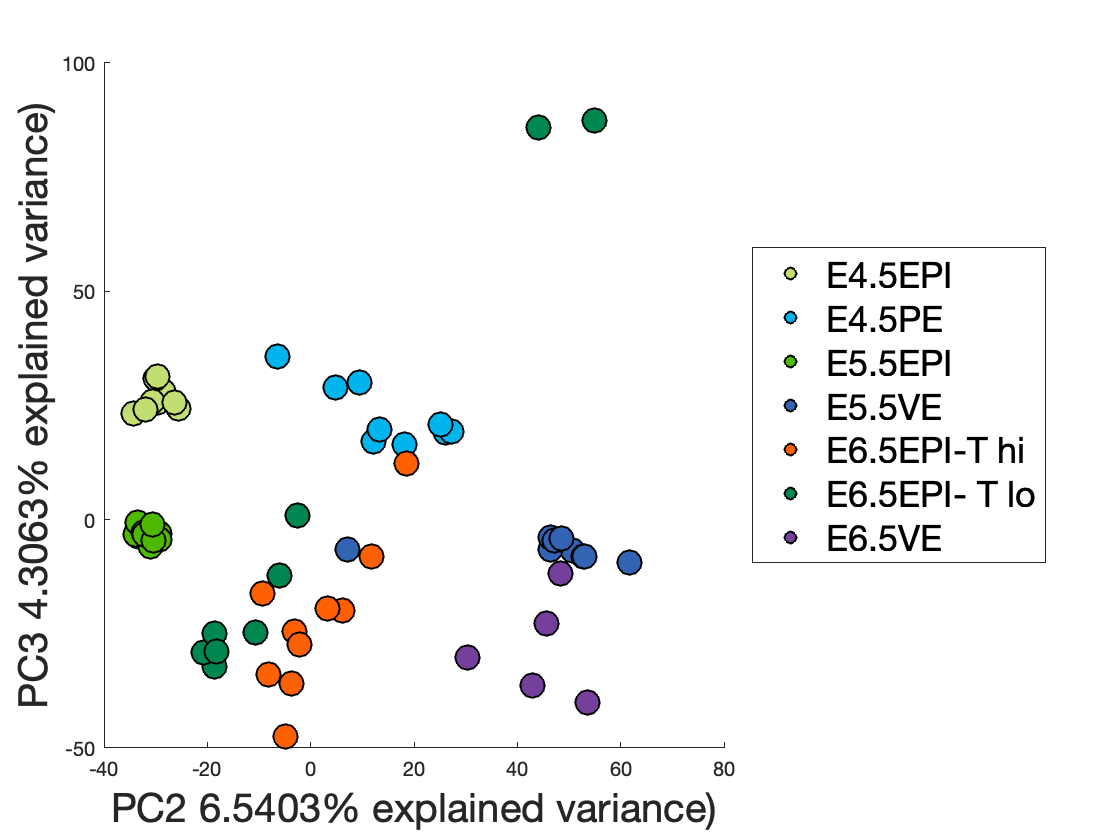

        figure;
    %     subplot(1,2,1);
        PCxx = 2; PCyy = 3;
        for colIdx = 1:7
            tempOGIdx = Ms_CellNames{celltypeIdx(colIdx),2}-2+436;
            tempEDIdx = [];
            for ii = 1:length(tempOGIdx)
                tempEDIdx = [tempEDIdx, find(MatcolIdx == tempOGIdx(ii))];
            end
            scatter(score(tempEDIdx,PCxx),score(tempEDIdx,PCyy),150,'MarkerEdgeColor',[0 0 0],'MarkerFaceColor',MsColor(colIdx,:),'LineWidth',1); hold on;
        end
        xeigenvalue = explained(PCxx);
        xlabel(['PC', num2str(PCxx), ' ', num2str(xeigenvalue),'% explained variance)'],'fontsize',20)
        % yeigenvalue = latent(2)/sum(latent);
        yeigenvalue = explained(PCyy);
        ylabel(['PC', num2str(PCyy), ' ', num2str(yeigenvalue),'% explained variance)'],'fontsize',20)
        legend('E4.5EPI','E4.5PE','E5.5EPI','E5.5VE','E6.5EPI-T hi','E6.5EPI- T lo','E6.5VE','Fontsize',18,'Location','eastoutside')
        hold off;


% 4. Average values in each cell type -> treat them more like bulk RNA-seq and then compare with my data

## version 1 code is gone due to computer auto shut down, but the plot is still in folder Figures/v1/

% Logic: cell2mat the values in v5_HgCyMs_translation (zscored one); pca
% the matrix all together; draw Cy alone, Ms alone and Cy, Ms, Hg
% altogether